## 数据类型、运算符与表达式

### **目标：**练习创建变量及类型转换

**内容：**

1.创建变量 date1，保存今天的日期

2.创建变量 num，赋值为 100

3.创建变量 date2，等于 date1 + num

查看上述变量的大小和数据类型

date1 = datetime('today');
num = 100;
date2 = date1 + num;
% View the size and type of the above variables
whos date1 date2 date3 num str is_same diff

  Name       Size            Bytes  Class       Attributes

  date1      1x1                 8  datetime              
  date2      1x1                 8  datetime              
  num        1x1                 8  double                



### **目标：**创建函数

**内容：**编写一个实现两数相加的函数

function y = calculateSum(x1, x2)
    y = x1 + x2;
end

y = calculateSum(7, 9.6)

y = 16.6000

## **目标：**了解各数据类型的取值范围

**内容：**使用 intmin、intmax、realmax、realmin返回各类数据类型的范围

% 整数类型范围
[intmin("int8") intmax("int8")]

ans = 1×2 int8 row vector
   -128    127


[intmin("int16") intmax("int16")]

ans = 1×2 int16 row vector
   -32768    32767


[intmin("int32") intmax("int32")]

ans = 1×2 int32 row vector
   -2147483648    2147483647


[intmin("int64") intmax("int64")]

ans = 1×2 int64 row vector
   -9223372036854775808    9223372036854775807


[intmin("uint8") intmax("uint8")]

ans = 1×2 uint8 row vector
     0   255


[intmin("uint16") intmax("uint16")]

ans = 1×2 uint16 row vector
       0   65535


[intmin("uint32") intmax("uint32")]

ans = 1×2 uint32 row vector
            0   4294967295


[intmin("uint64") intmax("uint64")]

ans = 1×2 uint64 row vector
                      0   18446744073709551615



% 浮点数类型范围
[-realmax('single') -realmin('single') realmin('single') realmax('single')]

ans = 1×4 single row vector
1.0e+38 *

   -3.4028   -0.0000    0.0000    3.4028


[-realmax -realmin realmin realmax]

ans = 1.0e+308 *

   -1.7977   -0.0000    0.0000    1.7977


## **目标：**进行数据类型强制转换

**内容：**将全为 1 的数组转换为复数数组

A = ones(2,3);
p = complex(1,1);
B = cast(A, 'like', p);

**内容：**将十六进制浮点数转换为十进制浮点数。

a = 'b6eae18b';
c = typecast(uint32(hex2dec(a)),'single');

### **目标：**了解浮点数的机器精度（Machine Epsilon）

**内容：**判断三组相同数字但顺序不同的等式结果是否相等

x1 = 0.33 - 0.5 + 0.17;
x2 = 0.33 + 0.17 - 0.5;
x3 = 0.17 - 0.5 + 0.33;

% 展示结果
fprintf('The value of x1 is %d.\n',x1);

The value of x1 is 2.775558e-17.


fprintf('The value of x2 is %d.\n',x2);

The value of x2 is 0.


fprintf('The value of x3 is %d.\n',x3);

The value of x3 is 5.551115e-17.


% 使用 “==” 来确定
disp(x1 == x2);

   0



disp(x1 == x3);

   0



disp(x2 == x3);

   0




%确定精度
disp(abs(x1-x2)<eps);

   1



disp(abs(x1-x3)<eps);

   1



disp(abs(x2-x3)<eps);

   1



X1、x2、x3应该是相同的，但由于这些数据是以二进制形式存储的，所以在使用双精度数表示时往往会出现一些不可避免的误差，但这些误差都小于eps。

### **目标：**练习算术运算符的使用

**内容：**计算下列数学表达式的值

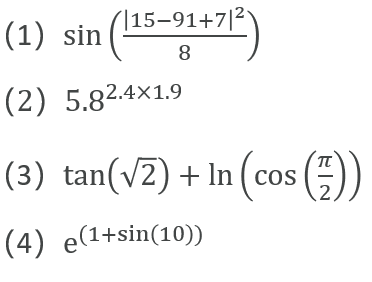

sin(abs(15-91+7)^2/8)

ans = -0.9787

5.8^(2.4*1.9)

ans = 3.0285e+03

tan(sqrt(2))+log(cos(pi/2))

ans = -30.9977

exp(1+sin(10))

ans = 1.5777

### **目的：**练习关系运算符的使用.

**内容：**在向量 A = [203 15 9 64 52 47 87 9 11] 中找出大于 60 的数的位置，并提取这些数

要求：使用关系运算符 “>”

A = [203 15 9 64 52 47 87 9 11];
I = find(A > 60)

I =      1     4     7


A(I)

ans =    203    64    87


### **目标：**练习逻辑运算符的使用

**内容**：找出并提取向量 [67 83 46 92 8 332 26 583] 中的所有偶数

要求：使用逻辑运算符 “~”

A = [67 83 46 92 8 332 26 583];
B = mod(A,2);
C = ~B;
A(C)

ans =     46    92     8   332    26


### **目标：**练习赋值运算符的使用

**内容：**使用 “=” 赋值以及 deal 函数赋值

% 直接赋值
x1 = 88;
fprintf('The value of x1 is %d.\n',x1);

The value of x1 is 88.



% 使用deal函数赋值
[y1, y2, y3] = deal(11);
fprintf('The value of y1 is %d.\n',y1);

The value of y1 is 11.


fprintf('The value of y2 is %d.\n',y2);

The value of y2 is 11.


fprintf('The value of y3 is %d.\n',y3);

The value of y3 is 11.


[z1, z2, z3] = deal(21, 22, 33);
fprintf('The value of z1 is %d.\n',z1);

The value of z1 is 21.


fprintf('The value of z2 is %d.\n',z2);

The value of z2 is 22.


fprintf('The value of z3 is %d.\n',z3);

The value of z3 is 33.


等号可以为单个变量赋值，deal函数可以同时为多个变量赋值。